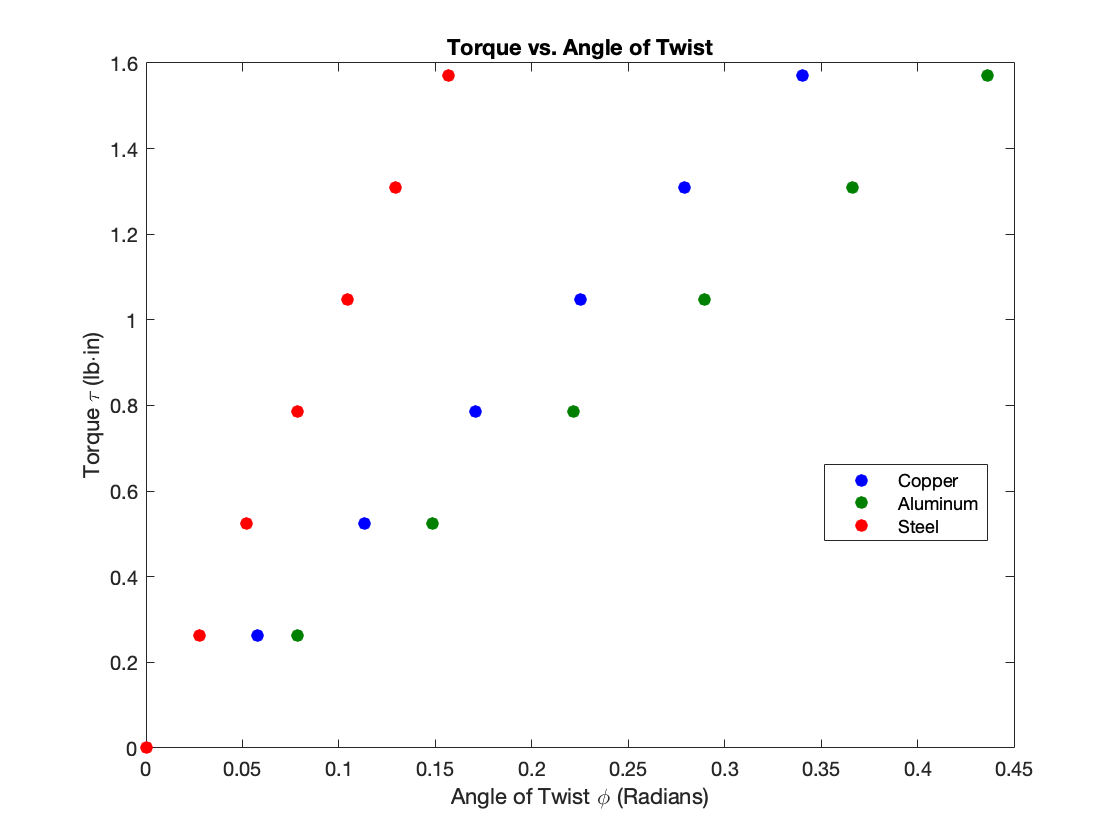

f_cu =      General model:
     f_cu(x) = a*x
     Coefficients (with 95% confidence bounds):
       a =       4.639  (4.604, 4.674)

% Mechanics of Materials Torsion Lab Analysis
raw_data = xlsread("Materials Lab 2 Data.xlsx");
increments = raw_data(:,1); % grams
copper_raw = raw_data(:,2);
aluminum_raw = raw_data(:,3);
steel_raw = raw_data(:,4);

% Convert angles from degrees into radians
copper = copper_raw * (pi/180);
aluminum = aluminum_raw * (pi/180);
steel = steel_raw * (pi/180);

% Convert increments into force (lbs)
increm_lbs = (increments/1000)*9.81*0.224809; % 1 Newton = 0.224809 lb-force

% Calculate uncertainty (assume error of 0.05 degrees)
error = 0.05 * (pi/180); % converted to radians

% Calculate torque (torque wheel diameter is 11.875 in)
torque = increm_lbs * (11.875/2);

% Plot all torques vs. angle of twist
plot(copper, torque, 'o', 'MarkerFaceColor','b', 'MarkerEdgeColor', 'b')
title('Torque vs. Angle of Twist')
xlabel('Angle of Twist \phi (Radians)')
ylabel('Torque \tau (lb\cdotin)')
hold on
plot(aluminum, torque, 'o', 'MarkerFaceColor', [0 0.5 0], 'MarkerEdgeColor', [0 0.5 0])
hold on
plot(steel, torque, 'o', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'r')
legend('Copper', 'Aluminum', 'Steel', 'Location',"best")
hold off
% Find best fit lines
p_cu=fittype('a*x','independent','x','dependent','y');  
f_cu=fit(copper,torque,p_cu)

p_al=fittype('a*x','independent','x','dependent','y');  
f_al=fit(aluminum,torque,p_al)

f_al =      General model:
     f_al(x) = a*x
     Coefficients (with 95% confidence bounds):
       a =       3.584  (3.546, 3.621)

p_st=fittype('a*x','independent','x','dependent','y');  
f_st=fit(steel,torque,p_st)

f_st =      General model:
     f_st(x) = a*x
     Coefficients (with 95% confidence bounds):
       a =       10.03  (9.937, 10.13)

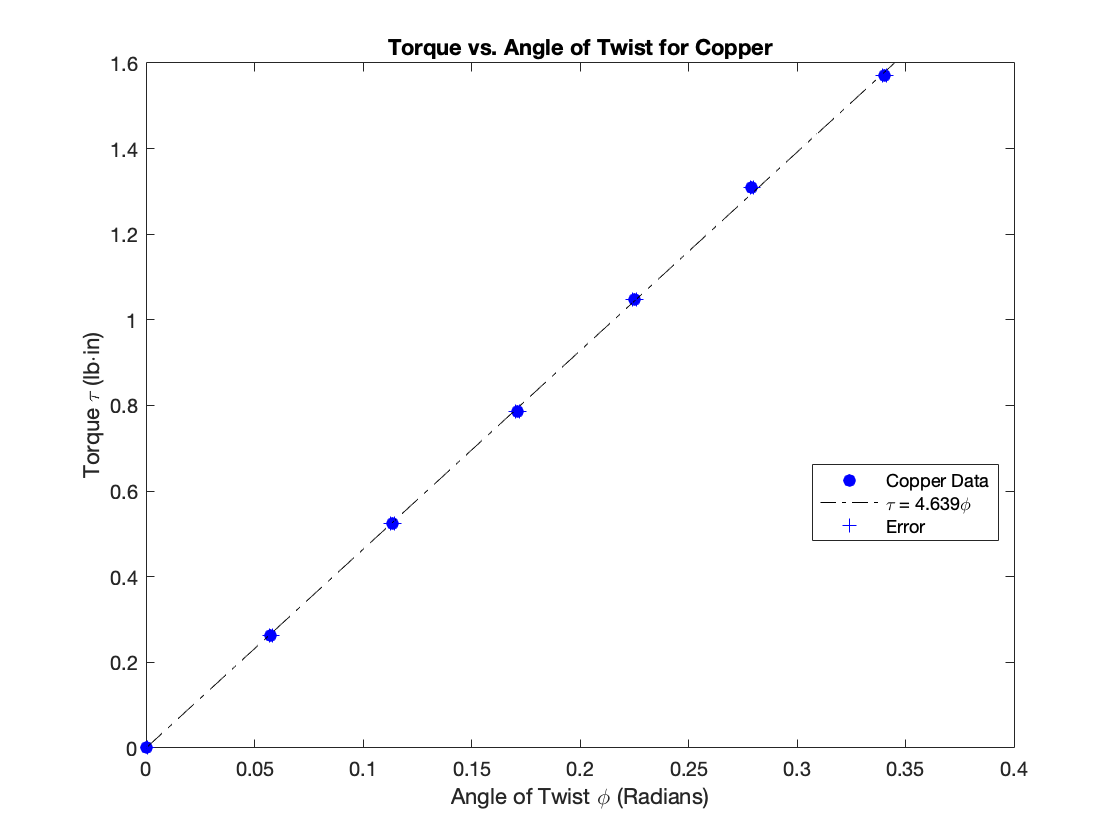

x_trend = linspace(0, 0.45,100);
y_cu = 4.639*x_trend;
y_al = 3.584*x_trend;
y_st = 10.03*x_trend;

% Individual plots with trendlines
figure
plot(copper, torque, 'o', 'MarkerFaceColor','b', 'MarkerEdgeColor', 'b')
title('Torque vs. Angle of Twist for Copper')
xlabel('Angle of Twist \phi (Radians)')
ylabel('Torque \tau (lb\cdotin)')
axis([0 0.4 0 1.6])
hold on
plot(x_trend, y_cu, 'k-.')
hold on
plot(copper+error, torque, 'b+')
hold on
plot(copper-error, torque, 'b+')
legend('Copper Data', '4.639, 'Error', 'Location',"best")
hold off

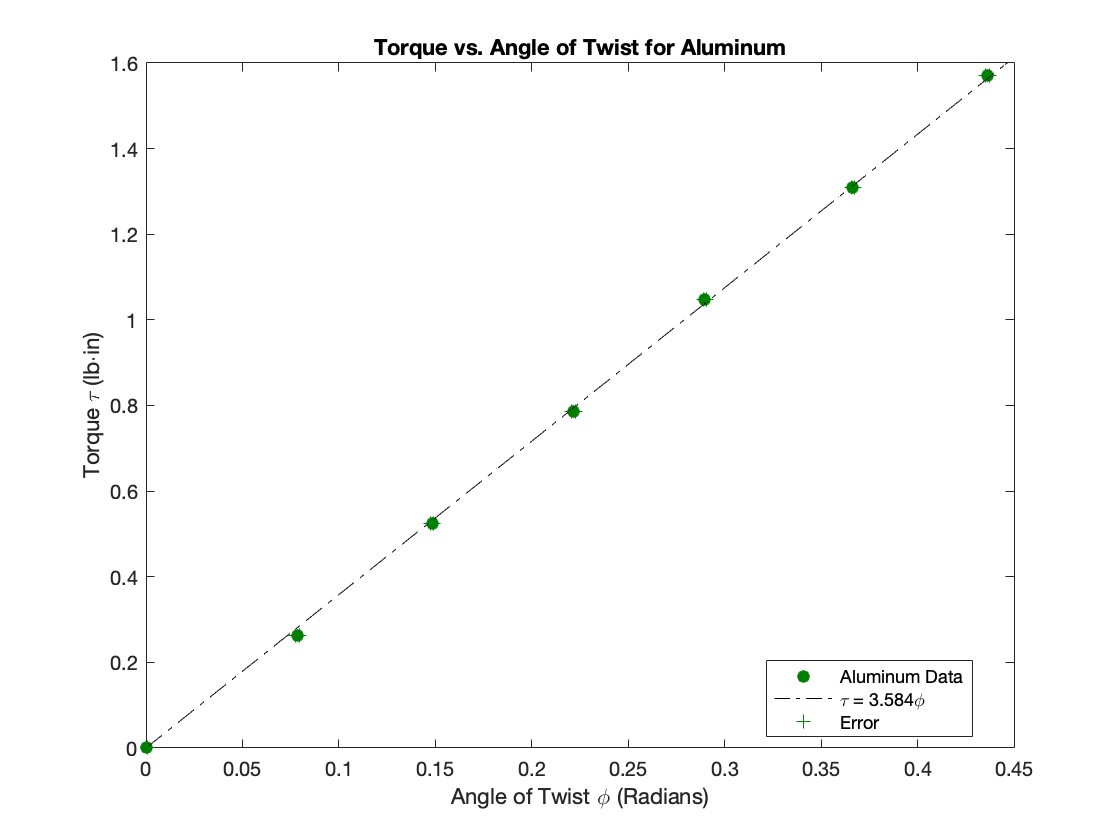

figure
plot(aluminum, torque, 'o', 'MarkerFaceColor', [0 0.5 0], 'MarkerEdgeColor', [0 0.5 0])
title('Torque vs. Angle of Twist for Aluminum')
xlabel('Angle of Twist \phi (Radians)')
ylabel('Torque \tau (lb\cdotin)')
axis([0 0.45 0 1.6])
hold on
plot(x_trend, y_al, 'k-.')
hold on
plot(aluminum+error, torque, '+', 'color', [0 0.5 0])
hold on
plot(aluminum-error, torque, '+', 'color', [0 0.5 0])
legend('Aluminum Data', '\tau = 3.584\phi', 'Error', 'Location',"best")
hold off

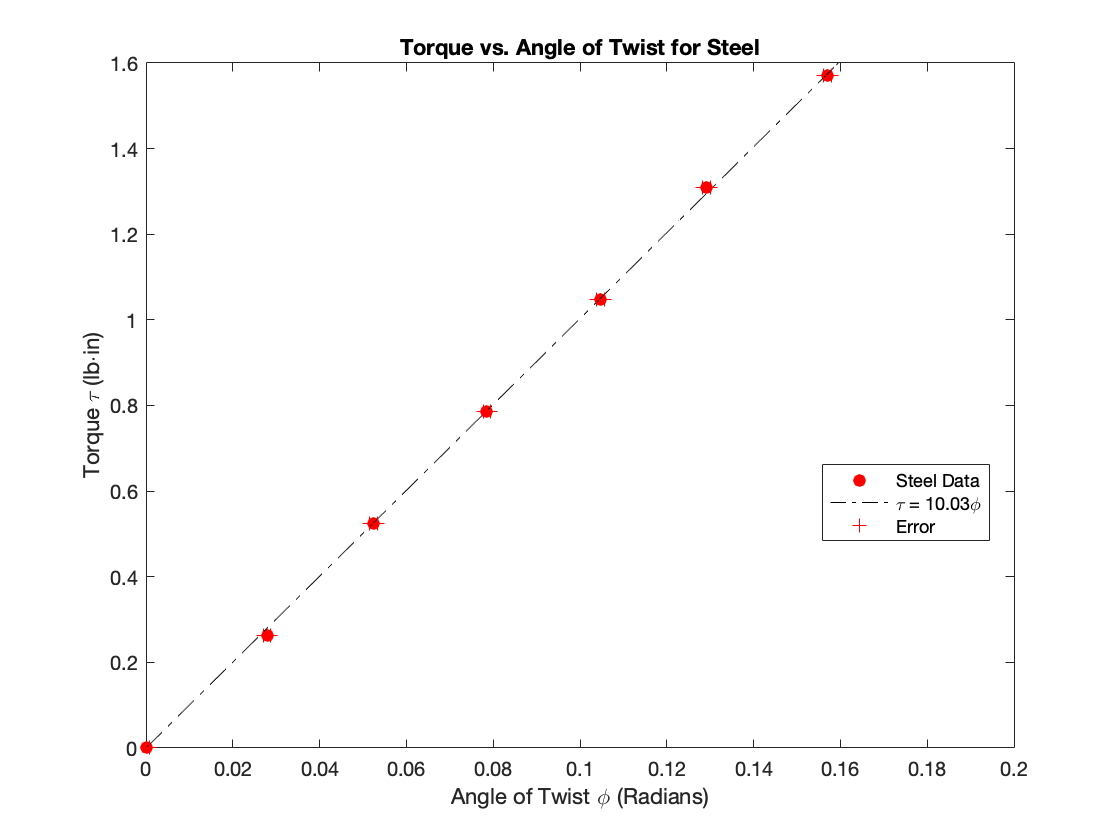

figure
plot(steel, torque, 'o', 'MarkerFaceColor','r', 'MarkerEdgeColor', 'r')
title('Torque vs. Angle of Twist for Steel')
xlabel('Angle of Twist \phi (Radians)')
ylabel('Torque \tau (lb\cdotin)')
axis([0 0.2 0 1.6])
hold on
plot(x_trend, y_st, 'k-.')
hold on
plot(steel+error, torque, 'r+')
hold on
plot(steel-error, torque, 'r+')
legend('Steel Data', '\tau = 10.03\phi', 'Error', 'Location',"best")
hold off


% Other Calculations
L = 23.75; % length of the shaft, inches
J = pi * ((0.125)^4)/32; % diameter of the shaft, inches
G_cu = 4.639*L/J;
G_al = 3.584*L/J;
G_st = 10.03*L/J;
fprintf('G for Copper: %.4f', G_cu)

G for Copper: 4596719.8909

fprintf('G for Aluminum: %.4f', G_al)

G for Aluminum: 3551335.2208

fprintf('G for Steel: %.4f', G_st)

G for Steel: 9938586.0112

torque

torque =          0
    0.2619
    0.5238
    0.7857
    1.0476
    1.3094
    1.5713


torque(2:7)

ans =     0.2619
    0.5238
    0.7857
    1.0476
    1.3094
    1.5713


J

J = 2.3968e-05